# **Лабораторная работа №1**

# **Синтез и фильтрация ШПС-сигналов типа M - последовательностей и кодов Уолша - Адамара**

**Выполнил: Голев Андрей Дмитриевич, ИВТ-32.**

**Преподаватель: Лавриненко Александр Дмитриевич.**

## Задача №1

Реализовать функцию **Mfun( A, C )**, представляющий собой цифровой автомат генерации **M - последовательности, **где 

- **A** - фаза;

- **C** - характеристический многочлен последовательности.

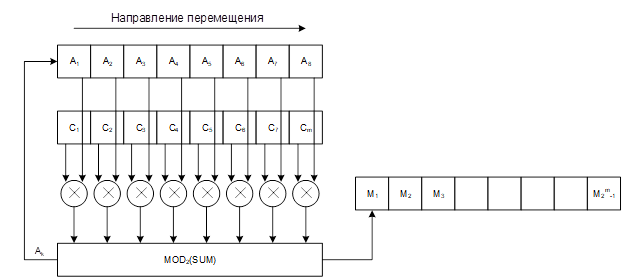

Сформировать две последовательности согласно своему варианту.

Полученные **M - последовательности **следует привести к виду [1; -1], проведя замену в исходных последовательностях:

- **0** на 1;

- **1** на -1.

clear; clc; close all;

% Вариант №6 

A   = [ 1 0 0 0 0 0 0 1 1 0 ];
C_1 = [ 0 0 1 1 1 0 0 1 1 1 ];
C_2 = [ 0 0 1 1 1 1 0 0 1 1 ];

M_1 = Mfun( A, C_1 );
M_2 = Mfun( A, C_2 );

M_1 = SubM(M_1);
M_2 = SubM(M_2);

Изобразить полученные М-последовательности на отдельных графиках.

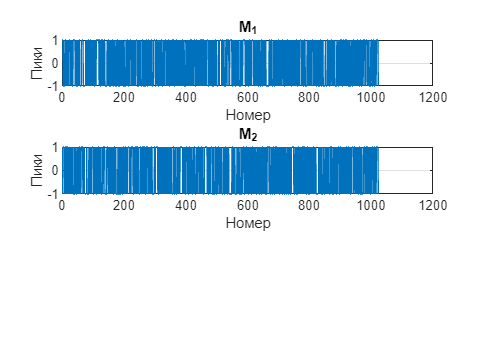

subplot( 3, 1, 1 )

plot( linspace( 1, length( M_1 ), length( M_1 ) ), M_1 )

title( "M_1" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

subplot( 3, 1, 2 )

plot( linspace( 1, length( M_2 ), length( M_2 ) ), M_2 )

title( "M_2" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №2

Сформировать сумму M-последовательностей $M_{\mathrm{сум}} =M_1 +M_2$, где $M_2$ взят со сдвигом и инверсией.

Сдвиг взять равным 100 + номер по списку в группе  * 10 <= length(M) / 2 

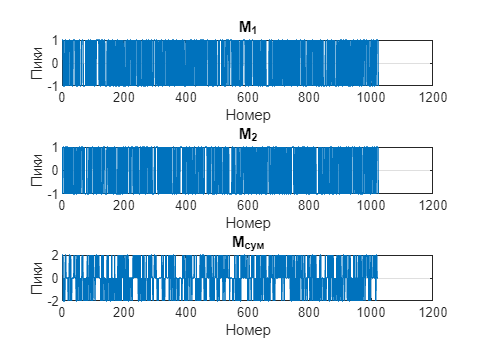

M_sum = M_1 + circshift( (M_2 * (-1) ), 160 );

subplot( 3, 1, 3 )

plot( linspace( 1, length( M_sum ), length( M_sum ) ), M_sum )

title( "M_{сум}" )
xlabel( "Номер" )
ylabel( "Пики" )

grid on

## Задача №3